%% Limpieza del entorno de trabajo
clear all;
clc;

%% Definir la ruta de la carpeta que contiene los archivos
folder_path = 'C:\Users\USER\OneDrive - UCO\2024-1\PDS\final\ejercicioFinal\archivos';  % Actualiza con la ruta correcta

%% Especificar el nombre del archivo MAT a cargar
mat_filename = '117m.mat';  % Actualiza con el nombre del archivo que deseas cargar

%% Construir el nombre completo del archivo MAT
mat_fullpath = fullfile(folder_path, mat_filename);

%% Verificar si el archivo MAT existe y cargar los datos
if exist(mat_fullpath, 'file') == 2
    % Cargar los datos del archivo MAT
    data_struct = load(mat_fullpath);
    
    % Suponiendo que la señal de ECG está almacenada en una variable llamada 'val'
    data_dat = data_struct.val; 
    
    % Mostrar los primeros 10 elementos de los datos
    fprintf('Primeros 10 elementos del archivo %s:\n', mat_filename);
    disp(data_dat(1:10));
    
    % Frecuencia de muestreo
    Fs = 200; % Actualiza esto con la frecuencia de muestreo correcta si es diferente
    
    %% Parte a - Señal original
    figure;
    plot(data_dat);
    title('a) Señal Original');
    xlabel('Muestras');
    ylabel('Amplitud');
    

 Salida del filtro pasa banda - cascada

 % Filtro Pasa Bajas: Frecuencia de corte 12 Hz
    fil_12hz_num = conv([1 0 0 0 0 0 -1], [1 0 0 0 0 0 -1]);
    fil_12hz_den = conv([1 -1], [1 -1]);
    electro_pb = filter(fil_12hz_num, fil_12hz_den, data_dat);
    
    % Filtro Pasa Altas: Frecuencia de corte 5 Hz
    Hd = finalfiltro5hz();
    [fil_5hz_num, fil_5hz_den] = sos2tf(Hd.sosMatrix, Hd.ScaleValues);
    electro_pb = filter(fil_5hz_num, fil_5hz_den, electro_pb);
    
    figure;
    plot(electro_pb);
    title('b) Salida del Filtro Pasa Banda');
    xlabel('Muestras');
    ylabel('Amplitud');

Salida del diferenciador

% Filtro Derivador
    num_der = [25 50 0 -50 -25];
    den_der = [1];
    electro_der = filter(num_der, den_der, electro_pb);
    
    figure;
    plot(electro_der);
    title('c) Salida del Diferenciador');
    xlabel('Muestras');
    ylabel('Amplitud');
    

Cuadratura

 electro_sq = electro_der.^2;
    
    figure;
    plot(electro_sq);
    title('d) Resultado del Proceso de Cuadratura');
    xlabel('Muestras');
    ylabel('Amplitud');

Integración con Ventana Móvil

N = 30; % Ventana de 150 ms (30 muestras a 200 Hz)
    num_samples = length(electro_sq);
    y = zeros(1, num_samples);
    for n = N:num_samples
        y(n) = (1 / N) * sum(electro_sq(n - (N - 1):n));
    end
    y(1:N-1) = 0;
    electro_mv = y;
    
    figure;
    plot(electro_mv);
    title('e) Resultados de la Integración con Ventana Móvil');
    xlabel('Muestras');
    ylabel('Amplitud');

Señal de ECG original con retraso

delay = round(N / 2);
    electro_delayed = [zeros(1, delay), data_dat(1:end-delay)];
    
    figure;
    plot(electro_delayed);
    title('f) Señal de ECG Original Retrasada');
    xlabel('Muestras');
    ylabel('Amplitud');

Detección de QRS

delay = round(N / 2);
    electro_delayed = [zeros(1, delay), data_dat(1:end-delay)];
    
    subplot(7, 1, 6);
    plot(electro_delayed);
    title('f) Señal de ECG Original Retrasada');
    xlabel('Muestras');
    ylabel('Amplitud');

Detección de QRS

Primeros 10 elementos del archivo 117m.mat:


  -102   -99   -97   -95   -93   -86   -81   -75   -70   -68



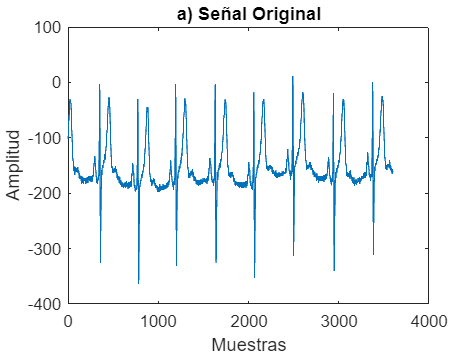

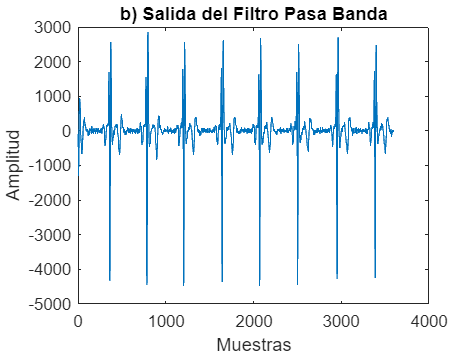

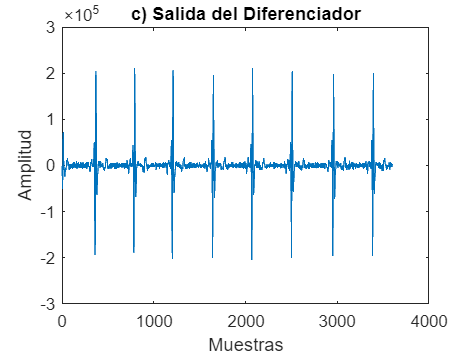

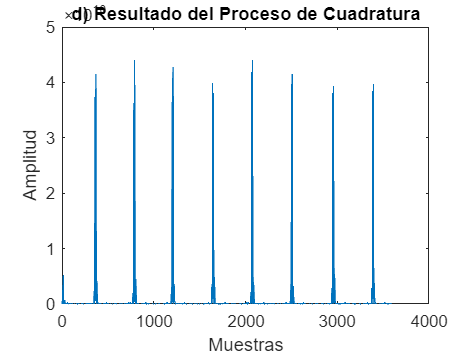

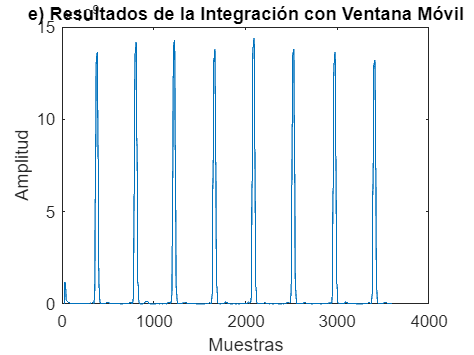

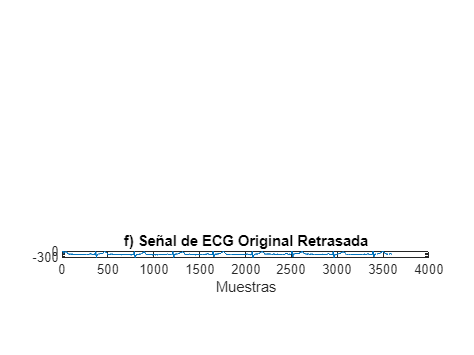

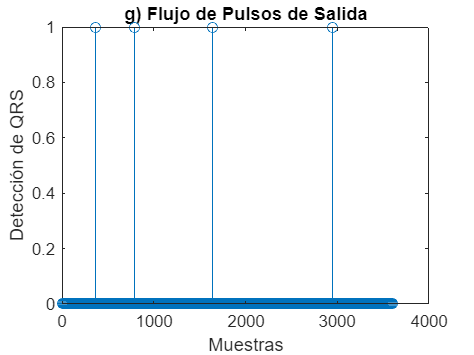

 % Inicialización de variables y umbrales
    threshold_signal = 0.6 * max(electro_mv);
    threshold_noise = 0.2 * max(electro_mv);
    RR_mean = 0;
    RR_interval = [];
    refractory_period = 0.2 * Fs; % 200 ms en muestras
    signal_peaks = [];
    noise_peaks = [];
    QRS_detected = [];
    
    % Detección de QRS
    for i = 1:length(electro_mv)
        if i > refractory_period && (isempty(RR_interval) || (i - RR_interval(end)) > 1.66 * RR_mean)
            if electro_mv(i) > threshold_signal
                if isempty(QRS_detected) || (i - QRS_detected(end)) > refractory_period
                    QRS_detected = [QRS_detected, i];
                    RR_interval = [RR_interval, i];
                    if length(RR_interval) > 1
                        RR_mean = mean(diff(RR_interval));
                    end
                    threshold_signal = 0.6 * max(electro_mv(QRS_detected));
                    threshold_noise = 0.2 * max(electro_mv(QRS_detected));
                end
            elseif electro_mv(i) > threshold_noise
                noise_peaks = [noise_peaks, electro_mv(i)];
            end
        end
    end
    
    % Generar flujo de pulsos de salida
    pulse_output = zeros(1, length(electro_mv));
    pulse_output(QRS_detected) = 1;
    
    figure;
    stem(pulse_output);
    title('g) Flujo de Pulsos de Salida');
    xlabel('Muestras');
    ylabel('Detección de QRS');
    
else
    fprintf('Error: El archivo MAT no existe en la ruta %s.\n', mat_fullpath);
end


%% Función para el Filtro Pasa Altas de 5 Hz

function Hd = finalfiltro5hz
    % FINALFILTRO5HZ Returns a discrete-time filter object.
    % MATLAB Code generated using the Signal Processing Toolbox.
    
    % All frequency values are in Hz.
    Fs = 200;  % Sampling Frequency
    
    N  = 2;  % Order
    Fc = 5;  % Cutoff Frequency
    
    % Construct an FDESIGN object and call its BUTTER method.
    h  = fdesign.highpass('N,F3dB', N, Fc, Fs);
    Hd = design(h, 'butter');
end